# Dynamic model of Otbot

This live script develops the dynamic model of Otbot and the solution to its forward and inverse dynamics problems.

Recall that the equation of motion of a robot takes the form

    
$$\mathbf{M}(\mathbf{q}) 
\; 
\ddot{\mathbf{q}} 
+ 
\mathbf{C}(\mathbf{q},\dot{\mathbf{q}}) 
\; 
\dot{\mathbf{q}} 
+ 
\mathbf{G}(\mathbf{q}) 
+ 
\mathbf{J}(\mathbf{q})^\top 
\; 
\mathbf{\lambda} 
= 
\mathbf{Q}_a(\mathbf{u})
+
\mathbf{Q}_f$$


where:

- $\mathbf{q}$ is the configuration vector of the robot (of size $n_q = 6$ in our case)

- $\mathbf{u} = [\mathbf{\tau}_r, \mathbf{\tau}_l, \mathbf{\tau}_p]^\top$ is the vector of motor torques (the right and left wheel torques and the platform torque).

- $\mathbf{M}\left(\mathbf{q}\right)$ is the mass matrix of the unconstrained system (positive-definite of size $\left.n_q \times n_q \right)$

- $\mathbf{C}\left(\mathbf{q},\dot{\mathbf{q}} \right)\;$is the generalized Coriolis and centrifugal force matrix

- $\mathbf{G}\left(\mathbf{q}\right)$ is the generalized gravity force

- $\mathbf{J}(\mathbf{q})$ is the constraint Jacobian of the robot

- $\mathbf{\lambda}$ is a vector of Lagrange mulitpliers.

- $\mathbf{Q}_a(\mathbf{u}) 
$ is the generalized force of actuation, which can be written in the form $\mathbf{E}(\mathbf{q}) \cdot \mathbf{u}$

- $\mathbf{Q}_f$ is the generalised force modelling all friction forces in the system

Note that, since the Otbot will move on flat terrain, $\mathbf{G}(\mathbf{q}) = \mathbf{0}$. Friction forces will also be neglected for the moment, so $\mathbf{Q}_f$ will be zero initially. The constraint Jacobian $\mathbf{J}(\mathbf{q})$ was already obtained in kinematic_model.mlx and we will simply load it from an appropriate mat file. 

Our task thus boils down to obtaining $\mathbf{M}(\mathbf{q})$, $\mathbf{C}(\mathbf{q},\dot{\mathbf{q}})$, and $\mathbf{E}(\mathbf{q})$ initially. After that, we will assemble the full dynamic model using the acceleration-level constraint (the time derivative of $\mathbf{J}\cdot\dot{\mathbf{q}} = \mathbf{0}$).

Hereafter, when we say "chassis" we mean the robot chassis **including** the wheels.

## 1. Initializations

% Clear all variables, close all figures, and clear the command window
clearvars 
close all
clc

% Start stopwatch
tic;

% Display the matrices with rectangular brackets
sympref('MatrixWithSquareBrackets',true); 

% Turn off abbreviated output format to avoid Matlab's own 
% substitution of long expressions)
% sympref('AbbreviateOutput',false); 

% Symbolic variables to be used (see the figures and explanations below)
syms x y             % Absolute coords of the pivot joint
syms x_dot y_dot     % Absolute velocity components of the pivot joint
syms alpha           % Absolute angle of the platform
syms alpha_dot       % Absolute angular velocity of the platform
syms varphi_r        % Angle of right wheel relative to chassis
syms varphi_l        % Angle of left wheel relative to chassis
syms varphi_p        % Pivot joint angle (platform wrt chassis)
syms varphi_dot_l    % Angular velocity of left wheel
syms varphi_dot_r    % Angular velocity of right wheel
syms varphi_dot_p    % Angular velocity of the platform relative to the chassis
syms l_1             % Pivot offset relative to the wheels axis
syms l_2             % One half of the wheels separation
syms m_c             % Mass of the chassis (including wheels) 
syms m_p             % Mass of the platform
syms x_F y_F         % Coords of F (c.o.m. of the platform) in platform frame
syms x_B y_B         % Coords of B (c.o.m. of the chassis) in chassis frame
syms I_p             % Vertical moment of inertia of the platform at its c.o.m.
syms I_a             % Axial moment of inertia of one wheel
syms I_c             % Vertical moment of inertia of the chassis at its c.o.m.

## 2. Computation of the mass matrix

Recall that the robot configuration is given by

    
$$\mathbf{q} = (x,y,\alpha, \varphi_r,\varphi_l,\varphi_p)$$


To find the mass matrix $\mathbf{M}(\mathbf{q})$ we first write the kinetic energy $T$ of the robot as a function of $\mathbf{q}$ and $\dot{\mathbf{q}}$ and then express it as:

    
$$T(\mathbf{q},\dot{\mathbf{q}}) = 
\frac{1}{2} \; 
\dot{\mathbf{q}}^\top 
\cdot 
\mathbf{M}(\mathbf{q}) 
\cdot 
\dot{\mathbf{q}}$$


We have to compute the translational and rotational kinetic energies of all bodies in the Otbot, and add them all to obtain $T$. 

% Chassis angle theta, and its derivative, in terms of qdot
theta = alpha - varphi_p;
theta_dot = alpha_dot - varphi_dot_p;
    
% Translational kinetic energies

    % Of the chassis
    T_tra_c = kin_en_trans(x_B, y_B, m_c, x_dot, y_dot, theta, theta_dot); 

    % Of the platform
    T_tra_p = kin_en_trans(x_F, y_F, m_p, x_dot, y_dot, alpha, alpha_dot);

% Rotational kinetic energies

    % Whole chassis including wheels
    T_rot_c = 1/2 * I_c * (theta_dot)^2;

    % Right wheel when turning about its axis alone
    T_rot_r = 1/2 * I_a * (varphi_dot_r)^2;

    % Left wheel when turing about its axis alone
    T_rot_l = 1/2 * I_a * (varphi_dot_l)^2;

    % Platform
    T_rot_p = 1/2 * I_p * (alpha_dot)^2;

% Total kinetic energy
T = T_tra_c + T_tra_p + ...
    T_rot_c + T_rot_r + T_rot_l + T_rot_p;

% Display the results
display(T_tra_c); display(T_tra_p);

$$T\_tra\_c = \frac{m_{c}\,{\dot{\alpha }}^{2}\,{x_{B}}^{2}}{2}+\frac{m_{c}\,{\dot{\alpha }}^{2}\,{y_{B}}^{2}}{2}-m_{c}\,\dot{\alpha }\,{\dot{\phi }}_{p}\,{x_{B}}^{2}-m_{c}\,\dot{\alpha }\,{\dot{\phi }}_{p}\,{y_{B}}^{2}-m_{c}\,\sin\left(\alpha -\phi_{p}\right)\,\dot{\alpha }\,x_{B}\,\dot{x}+m_{c}\,\cos\left(\alpha -\phi_{p}\right)\,\dot{\alpha }\,x_{B}\,\dot{y}-m_{c}\,\cos\left(\alpha -\phi_{p}\right)\,\dot{\alpha }\,\dot{x}\,y_{B}-m_{c}\,\sin\left(\alpha -\phi_{p}\right)\,\dot{\alpha }\,y_{B}\,\dot{y}+\frac{m_{c}\,{{\dot{\phi }}_{p}}^{2}\,{x_{B}}^{2}}{2}+\frac{m_{c}\,{{\dot{\phi }}_{p}}^{2}\,{y_{B}}^{2}}{2}+m_{c}\,\sin\left(\alpha -\phi_{p}\right)\,{\dot{\phi }}_{p}\,x_{B}\,\dot{x}-m_{c}\,\cos\left(\alpha -\phi_{p}\right)\,{\dot{\phi }}_{p}\,x_{B}\,\dot{y}+m_{c}\,\cos\left(\alpha -\phi_{p}\right)\,{\dot{\phi }}_{p}\,\dot{x}\,y_{B}+m_{c}\,\sin\left(\alpha -\phi_{p}\right)\,{\dot{\phi }}_{p}\,y_{B}\,\dot{y}+\frac{m_{c}\,{\dot{x}}^{2}}{2}+\frac{m_{c}\,{\dot{y}}^{2}}{2}$$

$$T\_tra\_p = \frac{m_{p}\,{\dot{\alpha }}^{2}\,{x_{F}}^{2}}{2}+\frac{m_{p}\,{\dot{\alpha }}^{2}\,{y_{F}}^{2}}{2}-m_{p}\,\sin\left(\alpha \right)\,\dot{\alpha }\,x_{F}\,\dot{x}+m_{p}\,\cos\left(\alpha \right)\,\dot{\alpha }\,x_{F}\,\dot{y}-m_{p}\,\cos\left(\alpha \right)\,\dot{\alpha }\,\dot{x}\,y_{F}-m_{p}\,\sin\left(\alpha \right)\,\dot{\alpha }\,y_{F}\,\dot{y}+\frac{m_{p}\,{\dot{x}}^{2}}{2}+\frac{m_{p}\,{\dot{y}}^{2}}{2}$$

display(T_rot_c); display(T_rot_r); display(T_rot_l); display(T_rot_p);

$$T\_rot\_c = \frac{I_{c}\,{\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)}^{2}}{2}$$

$$T\_rot\_r = \frac{I_{a}\,{{\dot{\phi }}_{r}}^{2}}{2}$$

$$T\_rot\_l = \frac{I_{a}\,{{\dot{\phi }}_{l}}^{2}}{2}$$

$$T\_rot\_p = \frac{I_{p}\,{\dot{\alpha }}^{2}}{2}$$

display(T);

$$T = \frac{I_{p}\,{\dot{\alpha }}^{2}}{2}+\frac{I_{a}\,{{\dot{\phi }}_{l}}^{2}}{2}+\frac{I_{a}\,{{\dot{\phi }}_{r}}^{2}}{2}+\frac{I_{c}\,{\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)}^{2}}{2}+\frac{m_{c}\,{\dot{x}}^{2}}{2}+\frac{m_{p}\,{\dot{x}}^{2}}{2}+\frac{m_{c}\,{\dot{y}}^{2}}{2}+\frac{m_{p}\,{\dot{y}}^{2}}{2}+\frac{{\dot{\alpha }}^{2}\,m_{c}\,{x_{B}}^{2}}{2}+\frac{{\dot{\alpha }}^{2}\,m_{p}\,{x_{F}}^{2}}{2}+\frac{{\dot{\alpha }}^{2}\,m_{c}\,{y_{B}}^{2}}{2}+\frac{{\dot{\alpha }}^{2}\,m_{p}\,{y_{F}}^{2}}{2}+\frac{m_{c}\,{{\dot{\phi }}_{p}}^{2}\,{x_{B}}^{2}}{2}+\frac{m_{c}\,{{\dot{\phi }}_{p}}^{2}\,{y_{B}}^{2}}{2}-\dot{\alpha }\,m_{c}\,{\dot{\phi }}_{p}\,{x_{B}}^{2}-\dot{\alpha }\,m_{c}\,{\dot{\phi }}_{p}\,{y_{B}}^{2}+\dot{\alpha }\,m_{c}\,x_{B}\,\dot{y}\,\cos\left(\alpha -\phi_{p}\right)-\dot{\alpha }\,m_{c}\,\dot{x}\,y_{B}\,\cos\left(\alpha -\phi_{p}\right)-\dot{\alpha }\,m_{c}\,x_{B}\,\dot{x}\,\sin\left(\alpha -\phi_{p}\right)-\dot{\alpha }\,m_{c}\,y_{B}\,\dot{y}\,\sin\left(\alpha -\phi_{p}\right)-m_{c}\,{\dot{\phi }}_{p}\,x_{B}\,\dot{y}\,\cos\left(\alpha -\phi_{p}\right)+m_{c}\,{\dot{\phi }}_{p}\,\dot{x}\,y_{B}\,\cos\left(\alpha -\phi_{p}\right)+m_{c}\,{\dot{\phi }}_{p}\,x_{B}\,\dot{x}\,\sin\left(\alpha -\phi_{p}\right)+m_{c}\,{\dot{\phi }}_{p}\,y_{B}\,\dot{y}\,\sin\left(\alpha -\phi_{p}\right)+\dot{\alpha }\,m_{p}\,x_{F}\,\dot{y}\,\cos\left(\alpha \right)-\dot{\alpha }\,m_{p}\,\dot{x}\,y_{F}\,\cos\left(\alpha \right)-\dot{\alpha }\,m_{p}\,x_{F}\,\dot{x}\,\sin\left(\alpha \right)-\dot{\alpha }\,m_{p}\,y_{F}\,\dot{y}\,\sin\left(\alpha \right)$$

Since $T
$ is a quadratic form, the Hessian of $T$ gives the desired mass matrix:

Mmat = hessian(T,[x_dot y_dot alpha_dot varphi_dot_r varphi_dot_l varphi_dot_p])

$$Mmat = \left[\begin{array}{cccccc} m_{c}+m_{p} & 0 & -m_{p}\,y_{F}\,\cos\left(\alpha \right)-m_{p}\,x_{F}\,\sin\left(\alpha \right)-m_{c}\,y_{B}\,\cos\left(\alpha -\phi_{p}\right)-m_{c}\,x_{B}\,\sin\left(\alpha -\phi_{p}\right) & 0 & 0 & m_{c}\,y_{B}\,\cos\left(\alpha -\phi_{p}\right)+m_{c}\,x_{B}\,\sin\left(\alpha -\phi_{p}\right)\\ 0 & m_{c}+m_{p} & m_{p}\,x_{F}\,\cos\left(\alpha \right)-m_{p}\,y_{F}\,\sin\left(\alpha \right)+m_{c}\,x_{B}\,\cos\left(\alpha -\phi_{p}\right)-m_{c}\,y_{B}\,\sin\left(\alpha -\phi_{p}\right) & 0 & 0 & m_{c}\,y_{B}\,\sin\left(\alpha -\phi_{p}\right)-m_{c}\,x_{B}\,\cos\left(\alpha -\phi_{p}\right)\\ -m_{p}\,y_{F}\,\cos\left(\alpha \right)-m_{p}\,x_{F}\,\sin\left(\alpha \right)-m_{c}\,y_{B}\,\cos\left(\alpha -\phi_{p}\right)-m_{c}\,x_{B}\,\sin\left(\alpha -\phi_{p}\right) & m_{p}\,x_{F}\,\cos\left(\alpha \right)-m_{p}\,y_{F}\,\sin\left(\alpha \right)+m_{c}\,x_{B}\,\cos\left(\alpha -\phi_{p}\right)-m_{c}\,y_{B}\,\sin\left(\alpha -\phi_{p}\right) & m_{c}\,{x_{B}}^{2}+m_{p}\,{x_{F}}^{2}+m_{c}\,{y_{B}}^{2}+m_{p}\,{y_{F}}^{2}+I_{c}+I_{p} & 0 & 0 & -m_{c}\,{x_{B}}^{2}-m_{c}\,{y_{B}}^{2}-I_{c}\\ 0 & 0 & 0 & I_{a} & 0 & 0\\ 0 & 0 & 0 & 0 & I_{a} & 0\\ m_{c}\,y_{B}\,\cos\left(\alpha -\phi_{p}\right)+m_{c}\,x_{B}\,\sin\left(\alpha -\phi_{p}\right) & m_{c}\,y_{B}\,\sin\left(\alpha -\phi_{p}\right)-m_{c}\,x_{B}\,\cos\left(\alpha -\phi_{p}\right) & -m_{c}\,{x_{B}}^{2}-m_{c}\,{y_{B}}^{2}-I_{c} & 0 & 0 & m_{c}\,{x_{B}}^{2}+m_{c}\,{y_{B}}^{2}+I_{c} \end{array}\right]$$

## 3. Computation of the Coriolis matrix

Recall that the $(i,j)$ element of $\mathbf{C}\left(\mathbf{q},\dot{\mathbf{q}} \right)$ is given by the following formula (see Murray, Sastry, Lee)

            ${\mathbf{C}}_{\textrm{ij}} =\frac{1}{2}\sum_{\mathrm{k}=1}^{\mathrm{n}} \left(\frac{\partial {\mathbf{M}}_{\textrm{ij}} }{\partial {\mathbf{q}}_{\mathrm{k}} }+\frac{\partial {\mathbf{M}}_{\textrm{ik}} }{\partial {\mathbf{q}}_{\mathrm{j}} }-\frac{\partial {\mathbf{M}}_{\textrm{kj}} }{\partial {\mathbf{q}}_{\mathrm{i}} }\right)\dot{{\mathbf{q}}_{\mathrm{k}} }$,

which in Matlab can be implemented as follows: 

qvec = [x y alpha varphi_r varphi_l varphi_p].';
qdotvec = [x_dot y_dot alpha_dot varphi_dot_r varphi_dot_l varphi_dot_p].';

nq = length(qvec);
Cmat = sym(zeros(nq,nq));

for i=1:nq
    for j=1:nq
        for k=1:nq
            Cmat(i,j) = Cmat(i,j) + qdotvec(k) * 0.5 * ( ...
                diff(Mmat(i,j),qvec(k)) + ...
                diff(Mmat(i,k),qvec(j)) - ...
                diff(Mmat(k,j),qvec(i))                   );
        end
    end
end
Cmat = simplify(Cmat);
display(Cmat)

$$Cmat = \left[\begin{array}{cccccc} 0 & 0 & \frac{{\dot{\phi }}_{p}\,\left(2\,m_{c}\,x_{B}\,\cos\left(\alpha -\phi_{p}\right)-2\,m_{c}\,y_{B}\,\sin\left(\alpha -\phi_{p}\right)\right)}{2}-\frac{\dot{\alpha }\,\left(2\,m_{p}\,x_{F}\,\cos\left(\alpha \right)-2\,m_{p}\,y_{F}\,\sin\left(\alpha \right)+2\,m_{c}\,x_{B}\,\cos\left(\alpha -\phi_{p}\right)-2\,m_{c}\,y_{B}\,\sin\left(\alpha -\phi_{p}\right)\right)}{2} & 0 & 0 & m_{c}\,\left(x_{B}\,\cos\left(\alpha -\phi_{p}\right)-y_{B}\,\sin\left(\alpha -\phi_{p}\right)\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)\\ 0 & 0 & \frac{{\dot{\phi }}_{p}\,\left(2\,m_{c}\,y_{B}\,\cos\left(\alpha -\phi_{p}\right)+2\,m_{c}\,x_{B}\,\sin\left(\alpha -\phi_{p}\right)\right)}{2}-\frac{\dot{\alpha }\,\left(2\,m_{p}\,y_{F}\,\cos\left(\alpha \right)+2\,m_{p}\,x_{F}\,\sin\left(\alpha \right)+2\,m_{c}\,y_{B}\,\cos\left(\alpha -\phi_{p}\right)+2\,m_{c}\,x_{B}\,\sin\left(\alpha -\phi_{p}\right)\right)}{2} & 0 & 0 & m_{c}\,\left(y_{B}\,\cos\left(\alpha -\phi_{p}\right)+x_{B}\,\sin\left(\alpha -\phi_{p}\right)\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right]$$

## 4. Generalized force of actuation

Our vector $\mathbf{u}$ of motor torques is defined as

    
$$\mathbf{u} = \left\lbrack 
\begin{array}{c}
\tau_r \\
\tau_l \\
\tau_p
\end{array}
\right\rbrack
$$


syms tau_r tau_l tau_p
uvec = [tau_r; tau_l; tau_p];

Each of the torques in $\mathbf{u}$ acts directly on a ${\dot{\mathbf{q}} }_{\mathrm{i}}$ coordinate and, therefore, the generalized force of actuation is given by

    
$$\mathbf{Q}_a 
= 
\left\lbrack 
\begin{array}{c}
0 \\
0 \\
0 \\
\tau_r \\
\tau_l \\
\tau_p
\end{array}
\right\rbrack
$$


To rewrite this force in the form $\mathbf{Q}_a = \mathbf{E} \cdot \mathbf{u}$ we only have to define

    
$$\mathbf{E}\left(\mathbf{q}\right)=\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


Ematrix = [zeros(3);eye(3)];

This completes our derivation of all matrices involved in the equation of motion.

## 5. Acceleration constraint

We now wish to obtain the robot model in the form $\dot{\mathit{\mathbf{x}}} =f\left(\mathit{\mathbf{x}},\mathit{\mathbf{u}}\right)\ldotp$ This requires writing $\dot{\mathbf{q}}$ and $\ddot{\mathbf{q}}$ as a function of $\mathbf{q}$, $\dot{\mathbf{q}}$, and $\mathbf{u}.$ Recall that the Euler-Lagrange equation is

    $\mathbf{M} \; \ddot{\mathbf{q}}
+
\mathbf{C} \; \dot{\mathbf{q}} 
+ 
{\mathbf{J}^{\top} 
\;
\mathbf{\lambda} 
=
\mathbf{E} \; \mathbf{u}$    (we omit the dependencies on $\mathbf{q}$ and $\dot{\mathbf{q}}$ for simplicity) 

Since this equation is a system of 6 equations in 9 unknowns (6 coordinates in $\ddot{\mathbf{q}}$ and 3 in $\mathbf{\lambda}
$) we need 3 additional equations to determine $\ddot{\mathbf{q}} \;$and $\mathbf{\lambda}$ for a given $\mathbf{u}$. These equations can be obtained by taking the time derivative of the kinematric constraint

    $\mathbf{J} 
\cdot
\dot{\mathbf{q}} =\mathbf{0}$,

which gives

    $\mathbf{J}
\;
\ddot{\mathbf{q}} 
+
\dot{\mathbf{J}} 
\;
\dot{\mathbf{q}} = \mathbf{0}$,

or, equivalently,

    
$$\mathbf{J}
\;
\ddot{\mathbf{q}} 
=
-
\dot{\mathbf{J}} 
\;
\dot{\mathbf{q}}$$


The latter equation is called the acceleration constraint of the robot. 

Recall that $\mathbf{J}$ was obtained in `kinematic_model.mlx. Therefore,` we only need to calculate its time derivative now:

% We first import J_of_q (obtained by an earlier run of kinematic_model.mlx)
load("constraint_jacobian.mat")

% Substitute its variables by functions of t and take the time derivative
syms f1(t) f2(t)
J_of_t = subs(J_of_q,[alpha varphi_p],[f1(t) f2(t)]);
dJdt = diff(J_of_t,t);

% Substitute d/dt of f1 and f2 by the original variables using dot notation
Jdot = subs(dJdt,[f1(t) f2(t) diff(f1,t) diff(f2,t)], ...
    [alpha varphi_p alpha_dot varphi_dot_p])

$$Jdot = \left[\begin{array}{cccccc} 0 & 0 & l_{1}\,\cos\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right) & \frac{r\,\sin\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)}{2} & \frac{r\,\sin\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)}{2} & -l_{1}\,\cos\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)\\ 0 & 0 & l_{1}\,\sin\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right) & -\frac{r\,\cos\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)}{2} & -\frac{r\,\cos\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)}{2} & -l_{1}\,\sin\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right]$$

## 6. Final model in explicit first-order form

The equations

    
$$\left\lbrace
\begin{array}{l}
\mathbf{M} \; \ddot{\mathbf{q}}
+
\mathbf{C} \; \dot{\mathbf{q}} 
+ 
{\mathbf{J}^{\top} 
\;
\mathbf{\lambda} 
=
\mathbf{E} \; \mathbf{u} \\
\mathbf{J}
\;
\ddot{\mathbf{q}} 
=
-
\dot{\mathbf{J}} 
\;
\dot{\mathbf{q}}
\end{array}
\right.

$$
 

can be written as a linear system with the form

    
$$\left\lbrack
\begin{array}{cc}
\mathbf{M}     &  {\mathbf{J}^\top \\
\mathbf{J} & \mathbf{0}
\end{array}\right\rbrack 
\left\lbrack
\begin{array}{c}
\ddot{\mathbf{q}} \\
\mathbf{\lambda} 
\end{array}\right\rbrack 
=
\left\lbrack 
\begin{array}{c}
\mathbf{E} \; \mathbf{u} - \mathbf{C} \; \dot{\mathbf{q}} \\
-\dot{\mathbf{J}} \; \dot{\mathbf{q}} 
\end{array}
\right\rbrack$$


and since $\mathbf{M}$ is positive-definite and $\mathbf{J}$ is full row rank, the matrix on the left-hand side can be inverted to write

    $\left\lbrack
\begin{array}{c}
\ddot{\mathbf{q}} \\
\mathbf{\lambda} 
\end{array}\right\rbrack 
=
{
\left\lbrack 
\begin{array}{cc}
\mathbf{M}       &      \mathbf{J}^\top \\
\mathbf{J} & \mathbf{0}
\end{array}
\right\rbrack
}^{-1} 

\left\lbrack 
\begin{array}{c}
\mathbf{E} \; \mathbf{u} - \mathbf{C} \; \dot{\mathbf{q}} \\
-\dot{\mathbf{J}} \; \dot{\mathbf{q}} 
\end{array}
\right\rbrack$.

Therefore

    $\ddot{\mathbf{q}} 
=
\left\lbrack 
\begin{array}{cc}
\mathbf{I}_{\mathrm{6}}  & \mathbf{0}
\end{array}
\right\rbrack 
{
\left\lbrack 
\begin{array}{cc}
\mathbf{M}       &      \mathbf{J}^\top \\
\mathbf{J} & \mathbf{0}
\end{array}
\right\rbrack
}^{-1} 

\left\lbrack 
\begin{array}{c}
\mathbf{E} \; \mathbf{u} - \mathbf{C} \; \dot{\mathbf{q}} \\
-\dot{\mathbf{J}} \; \dot{\mathbf{q}} 
\end{array}
\right\rbrack$.

Finally, by considering the trivial equation $\dot{\mathbf{q}} = \dot{\mathbf{q}}$ in conjunction with the earlier equation we arrive at 

    $\left\lbrack
\begin{array}{c}
\dot{\mathbf{q}} \\
\ddot{\mathbf{q}} 
\end{array}
\right\rbrack
=
\left\lbrack
\begin{array}{c}
\dot{\mathbf{q}} \\
\left\lbrack 
\begin{array}{cc}
\mathbf{I}_{\mathrm{6}}  & \mathbf{0}
\end{array}
\right\rbrack 
{
\left\lbrack 
\begin{array}{cc}
\mathbf{M}       &      \mathbf{J}^\top \\
\mathbf{J} & \mathbf{0}
\end{array}
\right\rbrack
}^{-1} 

\left\lbrack 
\begin{array}{c}
\mathbf{E} \; \mathbf{u} - \mathbf{C} \; \dot{\mathbf{q}} \\
-\dot{\mathbf{J}} \; \dot{\mathbf{q}} 
\end{array}
\right\rbrack

\end{array}
\right\rbrack
$,

which gives the robot model in the usual control form

    $\dot{\mathbf{x}} = f(\mathbf{x},\mathbf{u})$.

## 7. Solution to the forward dynamics problem

The forward dynamics problem consists in finding the acceleration $\ddot{\mathbf{q}}$ that corresponds to a given $\mathbf{u} = [\tau_r, \tau_l, \tau_p]^\top$. Such a $\ddot{\mathbf{q}}$ is given by the earlier expression

    $\ddot{\mathbf{q}} 
=
\left\lbrack 
\begin{array}{cc}
\mathbf{I}_{\mathrm{6}}  & \mathbf{0}
\end{array}
\right\rbrack 
{
\left\lbrack 
\begin{array}{cc}
\mathbf{M}       &      \mathbf{J}^\top \\
\mathbf{J} & \mathbf{0}
\end{array}
\right\rbrack
}^{-1} 

\left\lbrack 
\begin{array}{c}
\mathbf{E} \; \mathbf{u} - \mathbf{C} \; \dot{\mathbf{q}} \\
-\dot{\mathbf{J}} \; \dot{\mathbf{q}} 
\end{array}
\right\rbrack$.

## 8. Solution to the inverse dynamics problem

The inverse dynamics problem consists in finding the torques $\mathbf{u} = [\tau_r, \tau_l, \tau_p]^\top$ that produce a desired $\ddot{\mathbf{q}}$. These torques are obtained by solving

    
$$\mathbf{M} \; \ddot{\mathbf{q}}
+
\mathbf{C} \; \dot{\mathbf{q}} 
+ 
{\mathbf{J}^{\top} 
\;
\mathbf{\lambda} 
=
\mathbf{E} \; \mathbf{u}$$


for $\mathbf{u}$ and $\mathbf{\lambda}$ (6 equations and 6 unknowns). For this we define $\mathbf{\tau_{ID}} 
= 
\mathbf{M} \; \ddot{\mathbf{q}}
+
\mathbf{C} \; \dot{\mathbf{q}}$ and rewrite the previous equation as

    $
\mathbf{E} \; \mathbf{u}
-
{\mathbf{J}^{\top} 
\;
\mathbf{\lambda} 
=
\mathbf{\tau_{ID}} $,

or, equivalently, as

    $\left\lbrack 
\begin{array}{cc}
\mathbf{E}  & -\mathbf{J}^\top
\end{array}
\right\rbrack 
\;
\left\lbrack 
\begin{array}{c}
\mathbf{u} \\
\mathbf{\lambda}
\end{array}
\right\rbrack
=
\mathbf{\tau_{ID}}  
$.

It is easy to see that $\left\lbrack 
\begin{array}{cc}
\mathbf{E}  & -\mathbf{J}^\top
\end{array}
\right\rbrack $ is a $6 \times 6$ full rank matrix irrespectively of $\mathbf{q}$. This follows directly from the expressions of $\mathbf{E}$ and $\mathbf{J}$ in the Otbot.  Thus, we can write

    $
\left\lbrack 
\begin{array}{c}
\mathbf{u} \\
\mathbf{\lambda}
\end{array}
\right\rbrack
=
{
\left\lbrack 
\begin{array}{cc}
\mathbf{E}  & -\mathbf{J}^\top
\end{array}
\right\rbrack
}^{-1}
\;
\mathbf{\tau_{ID}}$,

so that

    
$$\mathbf{u}
=
\left\lbrack 
\begin{array}{cc}
\mathbf{I}_{\mathrm{3}}  & \mathbf{0}
\end{array}
\right\rbrack
\;
{
\left\lbrack 
\begin{array}{cc}
\mathbf{E}  & -\mathbf{J}^\top
\end{array}
\right\rbrack
}^{-1}
\;
\mathbf{\tau_{ID}}$$


provides the desired value for $\mathbf{u}$.

## 9. Save wokspace and main matrices to file

save("dynamic_model_workspace")
save('Mmatrix.mat',"Mmat")
save('Cmatrix.mat',"Cmat")

## 10. Print ellapsed time

toc

Elapsed time is 8.523805 seconds.


## Appendix: Function kin_en_trans

This function computes the translational kinetic energy of a point mass located at P on the grey body, in terms of the velocity coordinates $\dot{x}
$, $\dot{y}$, and $\dot{\theta}
$ of the body.

The following notation is used:

- $(c,d)$ = Local coordinates of P in the body-fixed frame {1',2'}

- $(x,y)$= Absolute coordinates of the origin of the body-fixed frame

- $\theta$ = absolute angle of the body

- $m$ = mass of P

                    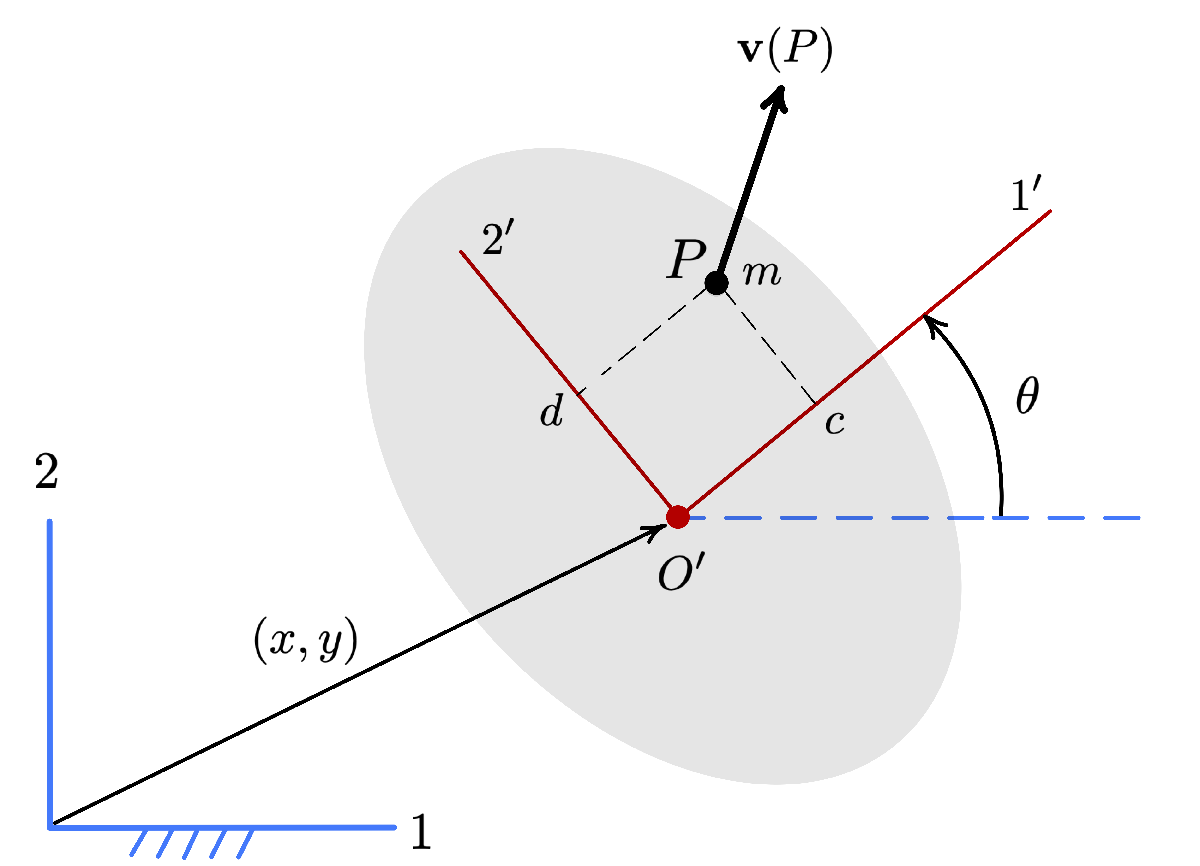

This function can be used to compute the translational kinetic energy of any body in planar motion. Just let P be the c.o.m. of the body, and m be the total mass of the body.

function T = kin_en_trans(c,d,m,xdot,ydot,theta,thetadot)

    cth = cos(theta);
    sth = sin(theta);

    A = [1,    0,    -cth * d - sth * c;
         0,    1,     cth * c - sth * d;
         0,    0,             1           ];
 
    Mp = [m, 0, 0; 0, m, 0; 0, 0, 0];
    M = simplify(transpose(A) * Mp * A);
    w = [xdot;ydot;thetadot];
    T = expand(1/2 * transpose(w) * M * w,'ArithmeticOnly',true);

end